# Forward Design Base Curve

Given a target pose and a load at the tip, and parameterized by the number of segments, find the set of valid arm base-curve geometries which will reach a target pose.

N_segs = 3;
g_target = Pose2.hat([0.5; -0.5; 0]);
g_0_o = Pose2.hat([0; 0; -pi/2]);
Q = [0; -3; 0];

% Define the range of base-curve parameters that we sweep over for the
% segments that we sweep (as opposed to the last segment, which is always
% derived).
l_range = [0.3, 0.3];
k_range = [0, 1];

N_l_samples = 1;
N_k_samples = 5;
ls = linspace(l_range(1), l_range(2), N_l_samples);
ks = linspace(k_range(1), k_range(2), N_k_samples);

[L, K] = meshgrid(ls, ks);
N_g_circs = N_l_samples * N_k_samples;
mat_g_circ_right = [L(:)'; zeros(1, N_l_samples * N_k_samples); K(:)'];

cell_mat_g_circ_right = cell(1, N_g_circs^(N_segs - 1));

counter = 1;
for i = 1 : size(mat_g_circ_right, 2)
    for j = 1 : size(mat_g_circ_right, 2)
        g_circ_right_1 = mat_g_circ_right(:, i);
        g_circ_right_2 = mat_g_circ_right(:, j);
        g_circ_right_3 = Twist2.vee(logm(Twist2.expm(-g_circ_right_2)* Twist2.expm(-g_circ_right_1) * inv(g_0_o) * g_target));

        cell_mat_g_circ_right{counter} = [g_circ_right_1, g_circ_right_2, g_circ_right_3];
        counter = counter + 1;
    end
end

seg = ArmSegment(Pose2, g_0_o, [], 0.5);
segs = repelem(seg, N_segs, 1);

arms = ArmSeries.empty(0, length(cell_mat_g_circ_right));
cell_g_ucirc_right = cell(1, length(cell_mat_g_circ_right));
for i = 1 : length(cell_mat_g_circ_right)
    arm_i = ArmSeries(copy(segs), "override_max_s", true);
    arm_i.g_circ_right = cell_mat_g_circ_right{i};

    cell_g_ucirc_right{i} = arm_i.calc_external_reaction(Q);

    arms(i) = arm_i;
end

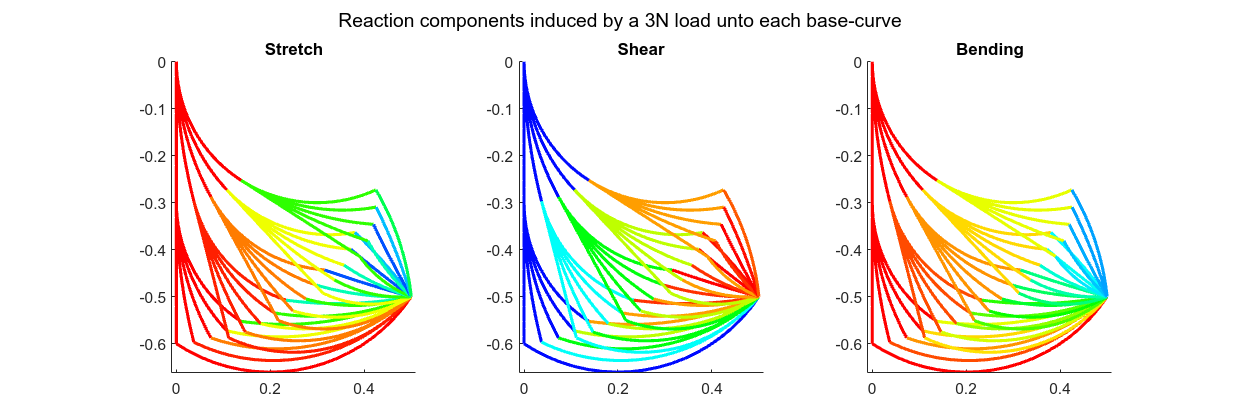

figure("Position", [0, 0, 1500, 500])

all_loads = [cell_g_ucirc_right{:}];
max_loads = max(abs(all_loads), [], 2);

dimensions = ["Stretch", "Shear", "Bending"];
for n = 1 : 3
    ax = subplot(1, 3, n);
    hold on

    for i_arm = 1 : length(arms)
        arm_i = arms(i_arm);
        g_ucirc_right_i = arm_i.calc_external_reaction(Q);
        for i_rod = 1 : N_segs
            rod_load = g_ucirc_right_i(:, i_rod);
            hsv_i = [0.66 - (0.66 * abs(rod_load(n)) / max_loads(n)), 1, 1];
            color_i = hsv2rgb(hsv_i);
            
            Plotter2D.plot_rod(arm_i.segments(i_rod).rod_o, ax, "color", color_i);
        end
    end

    title(dimensions(n));
end
sgtitle("Reaction components induced by a 3N load unto each base-curve")

N_segs = 4;
g_target = Pose2.hat([0.5; -0.5; 0]);
g_0_o = Pose2.hat([0; 0; -pi/2]);
Q = [0; -3; 0];

% Define the range of base-curve parameters that we sweep over for the
% segments that we sweep (as opposed to the last segment, which is always
% derived).
l_range = [0.17, 0.17];
k_range = [0, 1];

N_l_samples = 1;
N_k_samples = 5;
ls = linspace(l_range(1), l_range(2), N_l_samples);
ks = linspace(k_range(1), k_range(2), N_k_samples);

[L, K] = meshgrid(ls, ks);
N_g_circs = N_l_samples * N_k_samples;
mat_g_circ_right = [L(:)'; zeros(1, N_l_samples * N_k_samples); K(:)'];

cell_mat_g_circ_right = cell(1, N_g_circs^(N_segs - 1));

counter = 1;
for i = 1 : size(mat_g_circ_right, 2)
    for j = 1 : size(mat_g_circ_right, 2)
        for k = 1 : size(mat_g_circ_right, 2)
            for l = 1 : size(mat_g_circ_right, 2)
                g_circ_right_1 = mat_g_circ_right(:, i);
                g_circ_right_2 = mat_g_circ_right(:, j);
                g_circ_right_3 = mat_g_circ_right(:, k);
                pose_base_to_tip = g_0_o * Twist2.expm(g_circ_right_1) * Twist2.expm(g_circ_right_2) * Twist2.expm(g_circ_right_3);
                g_circ_right_4 = Twist2.vee(logm(inv(pose_base_to_tip) * g_target));
        
                cell_mat_g_circ_right{counter} = [g_circ_right_1, g_circ_right_2, g_circ_right_3, g_circ_right_4];
                counter = counter + 1;
            end
        end
    end
end

seg = ArmSegment(Pose2, g_0_o, [], 0.5);
segs = repelem(seg, N_segs, 1);

arms = ArmSeries.empty(0, length(cell_mat_g_circ_right));
cell_g_ucirc_right = cell(1, length(cell_mat_g_circ_right));
for i = 1 : length(cell_mat_g_circ_right)
    arm_i = ArmSeries(copy(segs), "override_max_s", true);
    arm_i.g_circ_right = cell_mat_g_circ_right{i};

    cell_g_ucirc_right{i} = arm_i.calc_external_reaction(Q);

    arms(i) = arm_i;
end

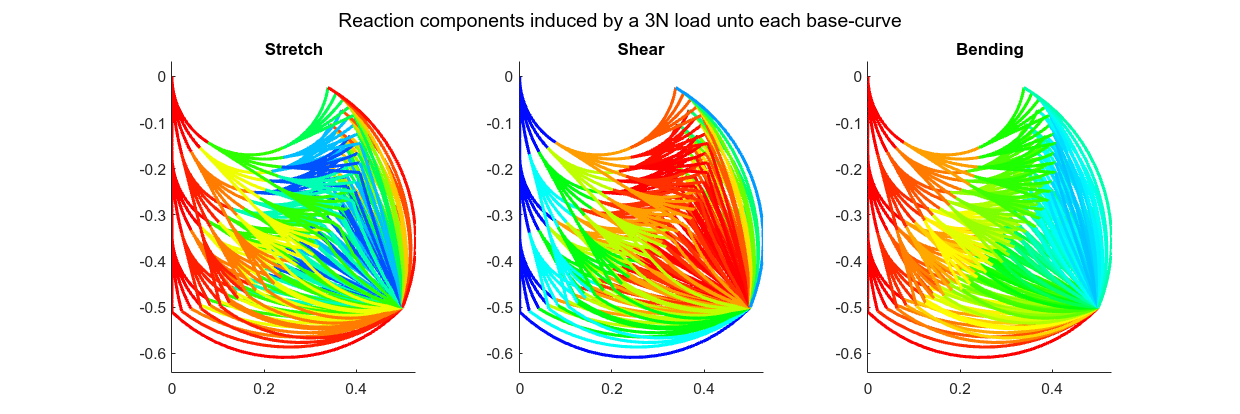

figure("Position", [0, 0, 1500, 500])

all_loads = [cell_g_ucirc_right{:}];
max_loads = max(abs(all_loads), [], 2);

dimensions = ["Stretch", "Shear", "Bending"];
for n = 1 : 3
    ax = subplot(1, 3, n);
    hold on

    for i_arm = 1 : length(arms)
        arm_i = arms(i_arm);
        g_ucirc_right_i = arm_i.calc_external_reaction(Q);
        for i_rod = 1 : N_segs
            rod_load = g_ucirc_right_i(:, i_rod);
            hsv_i = [0.66 - (0.66 * abs(rod_load(n)) / max_loads(n)), 1, 1];
            color_i = hsv2rgb(hsv_i);
            
            Plotter2D.plot_rod(arm_i.segments(i_rod).rod_o, ax, "color", color_i);
        end
    end

    title(dimensions(n));
end
sgtitle("Reaction components induced by a 3N load unto each base-curve")